# Quantize Network for CPU Deployment

To explore the behavior of a neural network with quantized convolution layers, use the **Deep Network Quantizer** app. This example quantizes the learnable parameters of the convolution layers of the `squeezenet` neural network after retraining the network to classify new images.

This example uses a [dlnetwork](docid:nnet_ref#object_dlnetwork) with the CPU execution environment.

Load the network to quantize into the base workspace.

load squeezedlnetmerch
net

net =   dlnetwork with properties:

         Layers: [67×1 nnet.cnn.layer.Layer]
    Connections: [74×2 table]
     Learnables: [52×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  View summary with summary.


Define calibration and validation data.

The app uses calibration data to exercise the network and collect the dynamic ranges of the weights and biases in the convolution and fully connected layers of the network and the dynamic ranges of the activations in all layers of the network. For the best quantization results, the calibration data must be representative of inputs to the network.

The app uses the validation data to test the network after quantization to understand the effects of the limited range and precision of the quantized learnable parameters of the convolution layers in the network.

In this example, use the images in the `MerchData` data set. Define an `augmentedImageDatastore` object to resize the data for the network. Then, split the data into calibration and validation data sets.

unzip('MerchData.zip');
imds = imageDatastore('MerchData', ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');
[calData, valData] = splitEachLabel(imds, 0.7, 'randomized');
aug_calData = augmentedImageDatastore([227 227], calData);
aug_valData = augmentedImageDatastore([227 227], valData);

At the MATLAB command prompt, open the app.

In the app, click **New** and select `Quantize a network`.

The app verifies your execution environment. For more information on selecting an execution environment, see [Quantization of Deep Neural Networks](docid:nnet_ug#mw_12e11582-96c6-4011-a7c6-7be206971ae5).

In the dialog, select the execution environment and the network to quantize from the base workspace. For this example, select a CPU execution environment and `net - dlnetwork`.

Select the **Prepare network for quantization** option. Network preparation modifies your neural network to improve performance and avoid error conditions in the quantization workflow. For more information, see [`prepareNetwork`](docid:nnet_ref#mw_9fbd6493-09da-4d05-9f9d-09adf4cd398e).

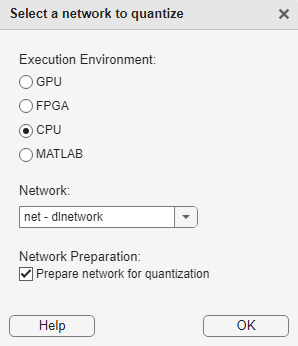

Click **OK**. The app displays the layer graph of the selected network.

In the **Calibrate** section of the toolstrip, under **Calibration Data**, select the `augmentedImageDatastore` object from the base workspace containing the calibration data, `aug_calData`. Select **Calibrate**.

The **Deep Network Quantizer** uses the calibration data to exercise the network and collect range information for the learnable parameters in the network layers.

When the calibration is complete, the app displays a table containing the weights and biases in the convolution and fully connected layers of the network as well as the dynamic ranges of the activations in all layers of the network and their minimum and maximum values during the calibration. To the right of the table, the app displays histograms of the dynamic ranges of the parameters.

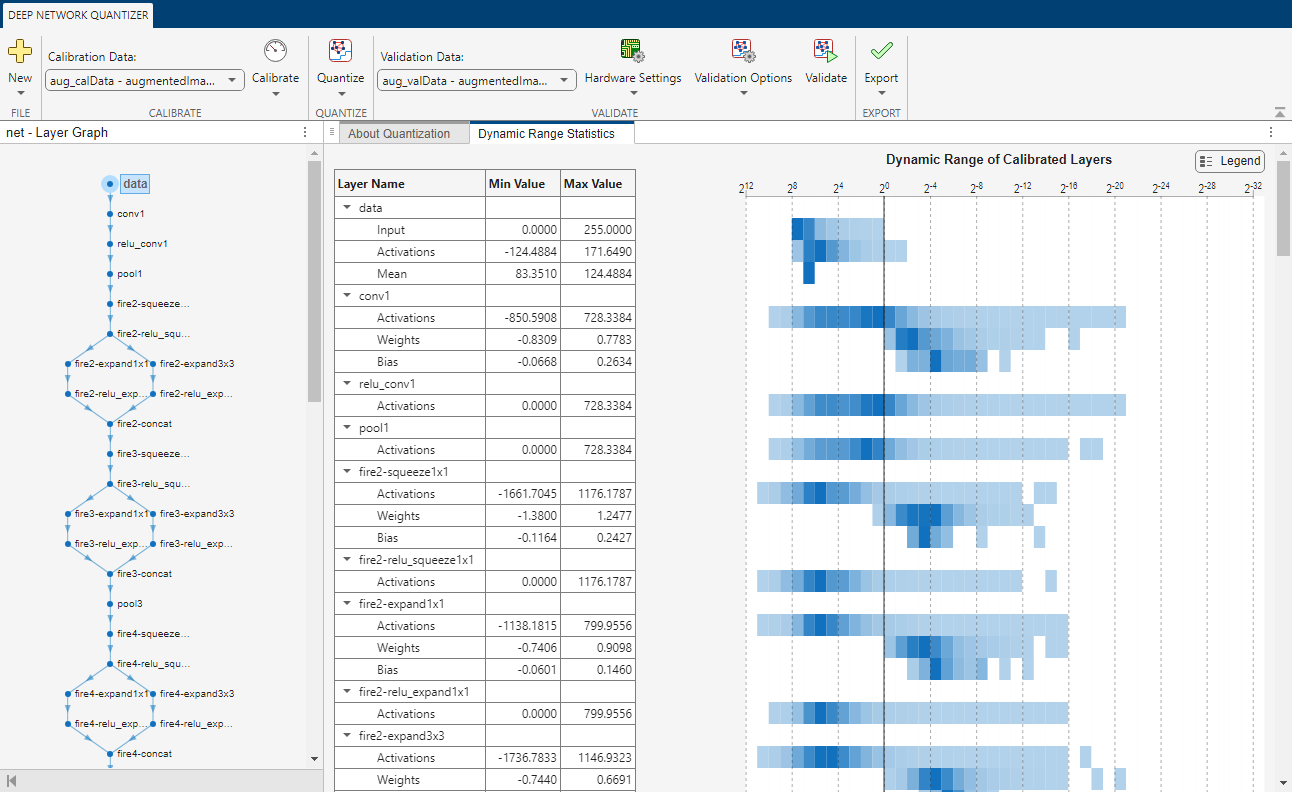

 In the **Quantize** section of the toolstrip, under **Quantize**, select the **MinMax** exponent scheme. Click **Quantize**.

The **Deep Network Quantizer** quantizes the weights, activations, and biases of convolution layers in the network to scaled 8-bit integer data types. The app updates the histogram of the dynamic ranges of the parameters. The gray regions of the histograms indicate data that cannot be represented by the quantized representation. For more information on how to interpret these histograms, see [Data Types and Scaling for Quantization of Deep Neural Networks](docid:nnet_ug#mw_1e8f4696-f380-467a-9f1f-e608673caec3).

In the **Quantize** column of the table, indicate whether to quantize the learnable parameters in the layer. Layers that are not quantized remain in single precision after quantization.

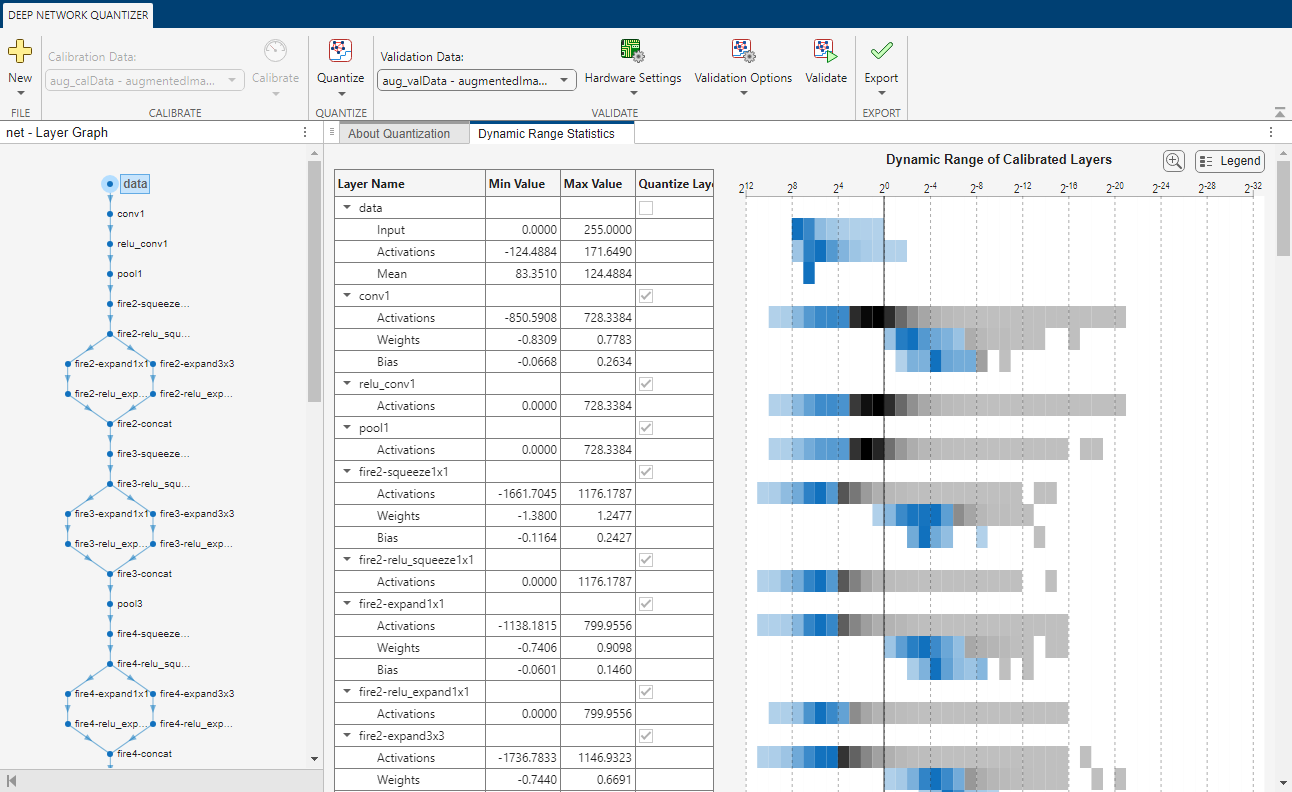

In the **Validate** section of the toolstrip, under **Validation Data**, select the `augmentedImageDatastore` object from the base workspace containing the validation data, `aug_valData`.

In the **Validate** section of the toolstrip, under **Hardware Settings**, select **Raspberry Pi** as the **Simulation Environment**. The app auto-populates the Target credentials from an existing connection or from the last successful connection. You can also use this option to create a new Raspberry Pi connection.

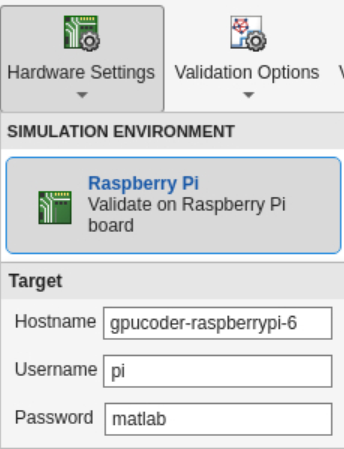

Define a custom metric function, `hComputeModelAccuracy`. Save this custom metric function in a local file.

In the **Validate** section of the toolstrip, under **Validation Options**, enter the name of the custom metric function, `hComputeModelAccuracy`. Select **Add** to add `hComputeModelAccuracy` to the list of metric functions available in the app. Select `hComputeModelAccuracy` as the metric function to use.

The custom metric function must be on the path. If the metric function is not on the path, this step causes an error.

Click **Validate**. The app uses the validation data to exercise the network.

When the validation is complete, the app displays the results of the validation, including:

- Metric function used for validation

- Result of the metric function before and after quantization

- Memory requirement of the network before and after quantization (MB)

If the performance of the quantized network is not satisfactory, you can explore the effects of choosing a different exponent selection scheme for quantization in the **Quantize** drop-down list. To see the effects of these changes, quantize and validate the network again.

After calibrating and quantizing the network, you can choose to export the quantized network or the `dlquantizer` object. Select the **Export** button. In the drop down, select from the following options:

- **Export Quantized Network** — Add the quantized network to the base workspace. This option exports a simulatable quantized network that you can explore in MATLAB without deploying to hardware.

- **Export Quantizer** —  Add the `dlquantizer` object to the base workspace. You can save the `dlquantizer` object and use it for further exploration in the **Deep Network Quantizer** app or at the command line, or use it to generate code for your target hardware.

- **Generate Code** — Open the **MATLAB Coder** app and generate C++ code from the quantized neural network. Generating C++ code requires a MATLAB Coder™ license.

*Copyright 2023-2024 The MathWorks, Inc.*